# 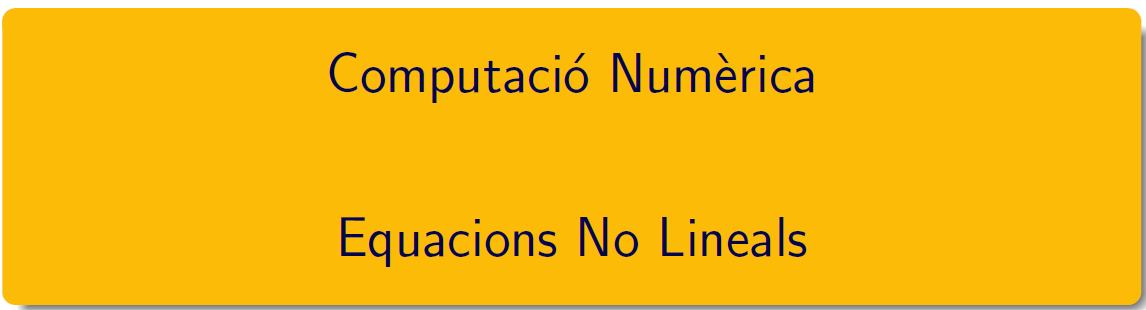

================================================================================

# Pràctica 7. Sistemes d'equacions no lineals.

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-Lab7.pdf i en el document CN_full5.pdf, els podeu trobar en el campus virtual. 

## Pràctica 16

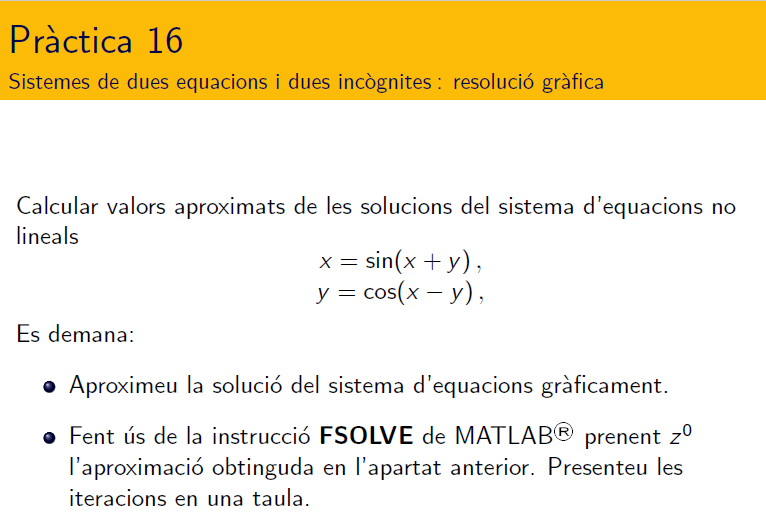

### Resolució Gràfica

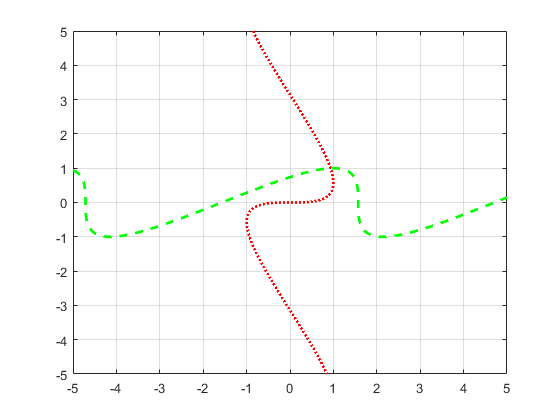

F1=@(x,y)x-sin(x+y);
F2=@(x,y)y-cos(x-y);
fimplicit(F1,[-5 5 -5 5],':r','LineWidth',2) % vull dibuixar la corba
hold on
fimplicit(F2,[-5 5 -5 5],'--g','LineWidth',2),grid
hold off

### Fsolve de Matlab®

Documentació de [fsolve](https://es.mathworks.com/help/optim/ug/fsolve.html)

Un enllaç amb documentació [Large-Scale Algorithms (Optimization Toolbox)](http://matrix.etseq.urv.es/manuals/matlab/toolbox/optim/opt3.html)

t=[1;1];
[x, fval] = fsolve(@myfun,t)    % Busca màxims i minims, on la derivada és 0


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x =       0.93508
      0.99802


fval =    5.2274e-12    1.759e-12


Resolució, amb iteracions

clearvars;
options = optimoptions('fsolve','Display','iter','StepTolerance',5e-15,'OptimalityTolerance',5e-15);
x0 = [2.1,2];
[x, fval] = fsolve(@myfun,x0,options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         9.52636                           4.7               1
     1          6         1.01153              1           1.49               1
     2          9       0.0198605        0.52227          0.199             2.5
     3         12     4.10204e-05      0.0890226        0.00857             2.5
     4         15     2.23505e-10     0.00451088       1.85e-05             2.5
     5         18     9.53884e-21    1.04552e-05       1.32e-10             2.5
     6         21               0     7.0226e-11              0             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function toleran

x =       0.93508      0.99802


fval =      0     0


## Pràctica 17

## 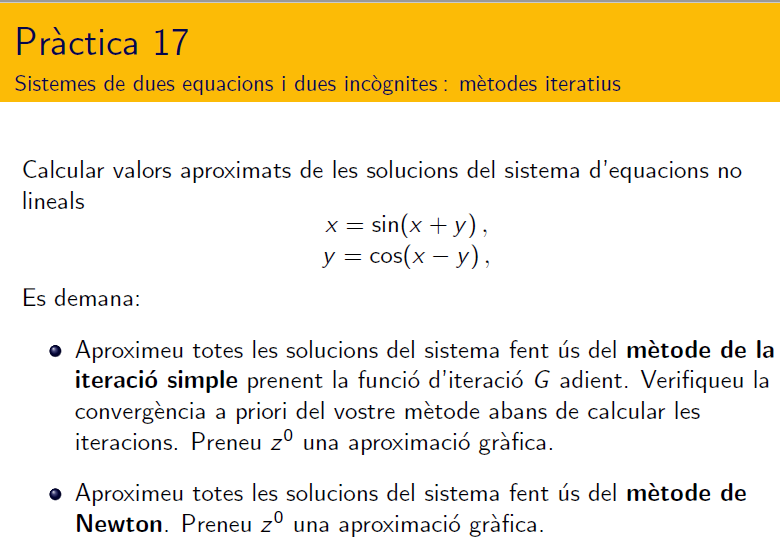

### Mètode de la iteració simple

#### Convergència a priori

format short g;
G1=@(x,y)sin(x+y);
G2=@(x,y)cos(x-y);
JG=@(x,y)[-cos(x+y),-cos(x+y); sin(x-y), -sin(x-y)];    % matriu jacobiniana
t=[1;1];
norm(JG(t(1),t(2)),1),norm(JG(t(1),t(2)),'inf')     % serà convergent

ans =       0.41615


ans =       0.83229


#### Cinc iteracions del mètode

t=[1;1];
for k=1:5
    t(1)=G1(t(1),t(2));
    t(2)=G2(t(1),t(2));
    disp([k,t'])
end

            1       0.9093      0.99589

            2      0.94461      0.99869

            3      0.93142      0.99774

            4      0.93647      0.99812

            5      0.93455      0.99798



F=@(x,y)[x-sin(x+y); y-cos(x-y)];
tolF=norm(F(t(1),t(2)),'inf');
disp(['solución = ',num2str(t')])

solución = 0.93455     0.99798


disp(['tolF = ',num2str(tolF)])

tolF = 0.00073269


disp(['iteraciones = ',num2str(k)])

iteraciones = 5


#### **Mètode del punt fix, amb control de l'error i del número d'iteracions**

% Per completar

### Mètode de Newton

#### Tres iteracions del mètode

clearvars; 
F=@(x,y)[x-sin(x+y); y-cos(x-y)];
JF=@(x,y)[1-cos(x+y),-cos(x+y); sin(x-y), 1-sin(x-y)];
t=[1;1]; 
for k=1:3
    y=linsolve(JF(t(1),t(2)),(-F(t(1),t(2))));
    t=t+y
end

t =       0.93595
            1


t =       0.93508
      0.99802


t =       0.93508
      0.99802


tolF=norm(F(t(1),t(2)),'inf');
tolX=norm(y,'inf');
disp(['solución = ',num2str(t')])

solución = 0.93508     0.99802


disp(['tolF = ',num2str(tolF)])

tolF = 5.2036e-12


disp(['tolX = ',num2str(tolX)])

tolX = 2.601e-06


disp(['iteraciones = ',num2str(k)])

iteraciones = 3


#### **Mètodo de Newton, amb control de l'error i del número d'iteracions**

% Per completar (el bucle està per ha de haber un control)

function F = myfun(x)  
    F(1) = x(1)-sin(x(1)+x(2)); 
    F(2) = x(2)-cos(x(1)-x(2)); 
end